# P6: Fit planes on 5 x 5 cm sections of point cloud

close all
clear all

Import functions to be used

import functions.fit_plane.*
import functions.projection_vector.*
import functions.deviations.*

Load cells of data and perform the rest of the operations consecutively

All the plots that are commented out show the plane fit results and deviations

histogram for each grid in the cloud. There are very many grids so it takes a while to plot everything. 

all_deviations = [];

datapath = '125voxels_flat_obj/cam1';
d=dir(fullfile(datapath,'*.csv'));
for i=1:numel(d)
  path = fullfile(datapath,d(i).name);
  data = load(path);
  % Avoid point clouds that have only one point
  % cannot fit plane to only one point
  if size(data, 1) > 2
      % Fit planes to each cloud cell
    [X, A] = fit_plane(data);
    b = data(:,3);
    
    % define how big the plane should be
    [x y] = meshgrid(min(data(:, 1)):max(data(:, 1)), min(data(:, 2)):max(data(:, 2)));
    % z = -A*x - B*y - D - equation of a plane, C = 1
    z = -X(1).*x - X(2).*y - X(3);
    
%     disp('Measurement ');
%     disp(int2str(i));

%     figure;
%     hold on;
%     s = surf(x,y,z);
%     s.EdgeColor = 'none';
%     s.FaceColor = 'black';
%     scatter3(data(:, 1), data(:, 2), b);
%     xlabel('X (mm)');
%     ylabel('Y (mm)');
%     zlabel('Z (mm)');
%     title("Plane least squares fit");

    % Get projected points
    Pb = projection_vector(data, X);

%     figure; 
%     hold on;
%     % plot the measurement points and the projected points using Pb with the
%     % correct adjusted height so see if I did it right
% 
%     scatter3(data(:, 1), data(:, 2), b);
%     scatter3(Pb(1,:),Pb(2, :),Pb(3, :), 'Marker', 'x', 'MarkerEdgeColor','y');
%     title('Measurement pts and projected pts by P');
%     xlabel('X (mm)');
%     ylabel('Y (mm)');
%     zlabel('Z (mm)');
%     legend('data','Pb proj');

    % Get the deviations on the z axis for each point.
    distance_to_plane = deviations(data, Pb, X);

    % Remove outliers that are 30 mm away from the fitted plane
    % These outlisers usually come from environmental factors such as
    % ambient light and are not exactly camera noise
    % That is why when looking at deviations on z axis, it is important
    % that far away outliers do not cause incorrect evaluation
    rows_to_delete = distance_to_plane < 30 & distance_to_plane > -30;
    distance_to_plane = distance_to_plane(rows_to_delete);

    all_deviations = [all_deviations; distance_to_plane];

    % Plot and analyze the noise distribution: mean and standard deviation. 
%     figure;
%     h = histogram(distance_to_plane);
%     xlabel('mm');
%     title("Deviations histogram");
  end
end

Calculate the variance and standard deviation from the mean value

variance = var(all_deviations)

variance = 0.0521

stdev = std(all_deviations)

stdev = 0.2282

meandev = mean(all_deviations)

meandev = 3.4680e-16

Now make one histogram with deviation data from all the clouds

figure;
h2 = histogram(all_deviations)

h2 =   Histogram with properties:

             Data: [239143×1 double]
           Values: [1 0 0 0 0 0 0 0 0 1 0 0 0 1 1 0 1 0 1 1 1 0 0 1 0 1 0 1 1 1 1 1 1 1 0 1 1 1 0 1 0 0 1 0 0 0 1 0 2 1 1 0 0 0 1 2 2 0 0 0 1 2 2 1 0 1 2 0 2 2 0 2 0 1 3 4 2 4 4 1 3 2 3 7 3 5 6 9 5 8 16 9 13 7 9 14 14 19 16 24 29 34 39 42 47 40 58 51 … ]
          NumBins: 366
         BinEdges: [-1.8000 -1.7900 -1.7800 -1.7700 -1.7600 -1.7500 -1.7400 -1.7300 -1.7200 -1.7100 -1.7000 -1.6900 -1.6800 -1.6700 -1.6600 -1.6500 -1.6400 -1.6300 -1.6200 -1.6100 -1.6000 -1.5900 -1.5800 -1.5700 -1.5600 -1.5500 -1.5400 -1.5300 … ]
         BinWidth: 0.0100
        BinLimits: [-1.8000 1.8600]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

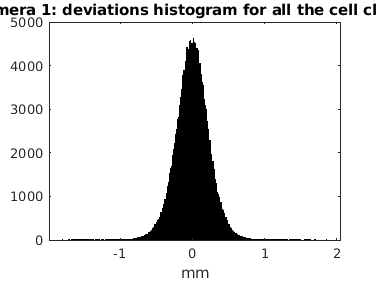

xlabel('mm');
title("Camera " + erase(datapath, "125voxels_flat_obj/cam") + ": deviations histogram for all the cell clouds");
saveas(gcf, "histogram_z_noise_cam" + erase(datapath, "125voxels_flat_obj/cam"), 'png')